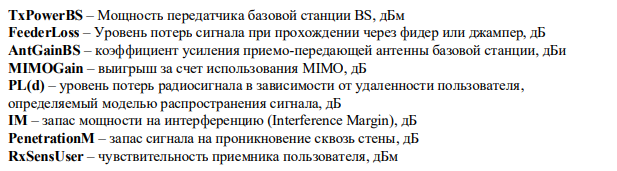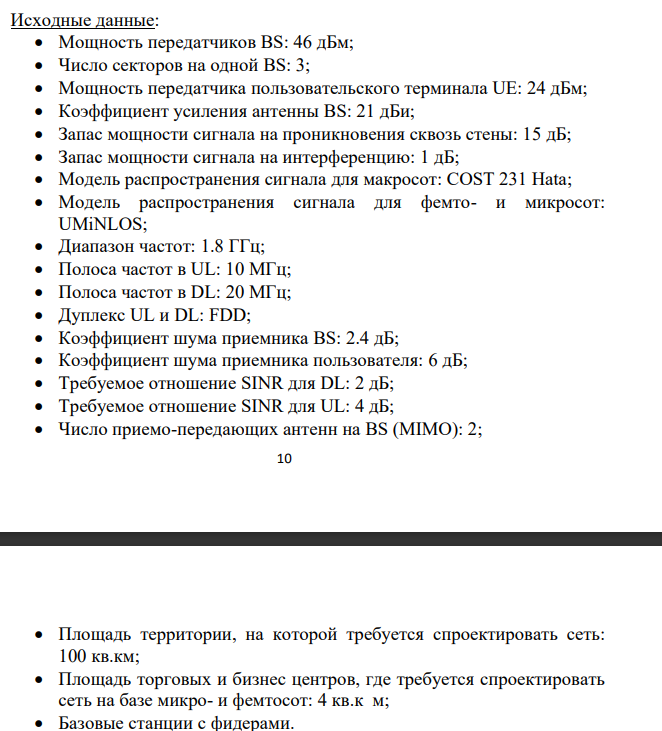

function z = MAPL_DL()
    TxPowerUE = 46; %дБм 
    FeederLoss = 2; %дБ
    AntGainBS = 21; %дБи
    MIMOGain = 3; %дБ
    IM = 1; %дБ
    PenetrationM = 15; %дБ
    NoiseFigure = 6; %дБ 
    ThermalNoise = -174 + 10 * log10(20 * 10 ^ 6); %дБ
    ReqiredSINR = 2; %дБ
    RxSens = NoiseFigure + ThermalNoise + ReqiredSINR;
    z = TxPowerUE - FeederLoss + AntGainBS + MIMOGain - RxSens - IM - PenetrationM;
end